## Grid-Topology Estimation for Supervisory Control of Microgrids

This script is made in order to estimate a Microgrid admitance matrix.

To do so, Matpower have been used ([https://matpower.org/.](https://matpower.org/.)). Matpower is an open source Matlab module made to simulate powerflow. This module as been used the simulate the network but also to access test cases

close all; clc; clear all;

# Part 1: Constants & Network definition

In this first section, the network will be defined from a Matpower test case. It will permit to have to real admitance matrix (benchmark), voltage and current data.

First, we'll set a random seed in order to have comparable experiments.

rng(11);

We load the data and we define the simulation setup to be used.

A test case can be chosen by filling the "loadcase" function

Noise can be added in the measurements trought** noise_v_sd **and **noise_i_sd**

define_constants;  % Matpower conventions
samples = 500;
noise_v_sd = 0;
noise_i_sd = 0;
random_load_power_cv = 0.1;
mpc = loadcase('case118');

We define useful constants and we derive the impedence matrix **Y**.

The impedence matrix **Y** is displayed as a heatmap in order to vizualize the situation with one glance.

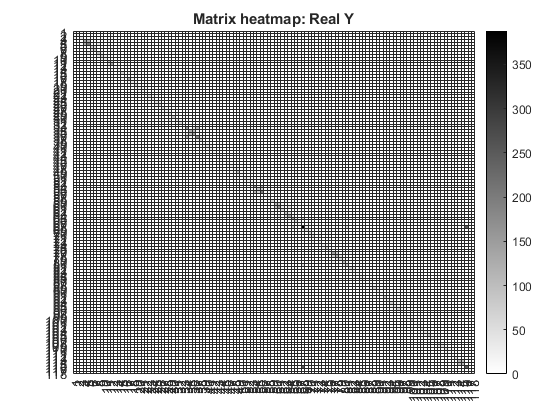

Y = full(makeYbus(mpc));
load_mask = mpc.bus(:, BUS_TYPE) == PQ;
controllable_mask = mpc.bus(:, BUS_TYPE) == PV;
n = size(mpc.bus, 1);
n_gen = size(mpc.gen, 1);
n_controllable = sum(controllable_mask);
n_load = n - n_gen;
matrix_heatmap(Y, 'Real Y');

We check that the admittance matrix is in Laplacian.

is_laplacian(Y)

ans = logical
   1


# Part 2: Grid simulation

In the second section, we will simulate the grid from the previously created admitance matrix. It will allow us the create the voltage and current data that will be used to estimate the admitance matrix. 

%simulate = true;
simulate = false;

if simulate
    bus_voltage = [];
    for j = 1:10
        load_avg_pd = mpc.bus(load_mask, PD);
        load_avg_qd = mpc.bus(load_mask, QD);
        bus_voltage_temp = zeros(n, samples);
        load_pd = zeros(size(load_avg_pd, 1), samples);
        load_qd = zeros(size(load_avg_qd, 1), samples);
        for i = 1:samples
            mpc.bus(load_mask, PD) = normrnd(load_avg_pd, random_load_power_cv * abs(load_avg_pd));
            mpc.bus(load_mask, QD) = normrnd(load_avg_qd, random_load_power_cv * abs(load_avg_qd));
            res = runpf(mpc);
            bus_phase = res.bus(:, VA) * pi / 180;
            bus_magnitude = res.bus(:, VM);
            bus_voltage_temp(:, i) = bus_magnitude .* (cos(bus_phase) + sqrt(-1) * sin(bus_phase));
            load_pd(:, i) = res.bus(load_mask, PD);
            load_qd(:, i) = res.bus(load_mask, QD);
        end
        bus_voltage = [bus_voltage bus_voltage_temp];
    end
    save(sprintf('save_%d_%d.mat', n, random_load_power_cv),'bus_voltage');
else
    bus_voltage = load(sprintf('save_%d_%d.mat', n, random_load_power_cv)).bus_voltage;
end

The voltage obtained with the simulation are theorical, but the application of the identification algorithm concerns measurement data. This is why white noise is applied to the measurements.

ev = normrnd(0, noise_v_sd, size(bus_voltage));
ei = normrnd(0, noise_i_sd, size(bus_voltage));
bus_current = Y * bus_voltage + ei;
bus_voltage = bus_voltage + ev;

Here is some exemple of bus voltage and current.

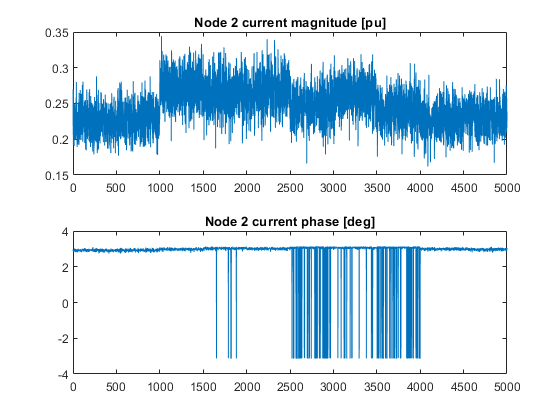

viz_node = 2;
viz_current = bus_current(viz_node, :);
viz_voltage = bus_voltage(viz_node, :);

figure()
subplot(2, 1, 1);
plot(1:size(abs(viz_current), 2), abs(viz_current));
title(sprintf('Node %d current magnitude [pu]', viz_node));
subplot(2, 1, 2);
plot(1:size(angle(viz_current), 2), angle(viz_current));
title(sprintf('Node %d current phase [deg]', viz_node));

# Part 3: Error metrics

We define the error metrics we are going to use to test the accuracy of the estimation algorithms. Define the error matrix $Y_e = \left |Y - \hat Y \right|$. We are going to use the following error metrics:

- Frobenius norm of $Y_e$

- Max norm of $Y_e$

Moreover, we will resort to an heatmap to see how the absoulte error in the estimation of the admittance matrix is distributed among the different elements.

# Part 4: Admitance matrix indentification benchmark

The goal of the project is to identify the admitance matrix of the grid with specific algorithms, thus it is interesting to compare it with traditional methods in order to compare the difference of performances but also to justify the use of more complex methods.

The benchmark chose is the ordinary least squared estimation.

Y_hat_ols = conj(bus_voltage' \ bus_current');

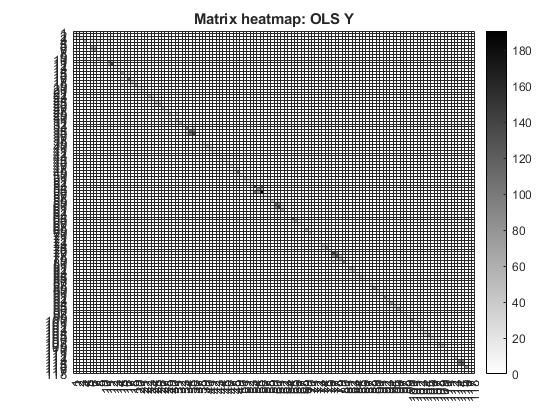

matrix_heatmap(Y_hat_ols, 'OLS Y');

With one glance, we are able to see that the OLS estimation performs very poorly.

Froebius norm for OLS is 736.4121
Max norm for OLS is 387.6481


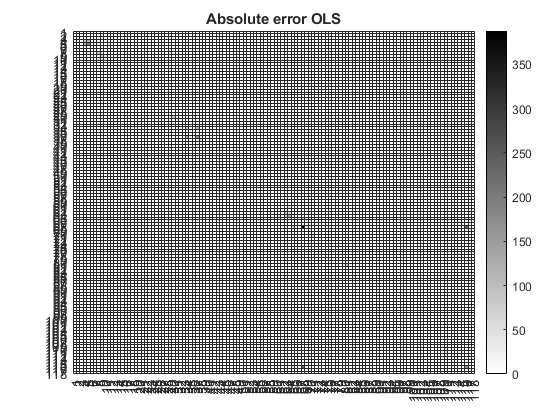

[ols_froeb_error, ols_max_error, chart] = error_metrics(Y, Y_hat_ols, 'OLS');

# Part 5: First least square estimation with low rank measures

There is $n^2$ parameters to estimate, those parameters correspond to a graph edges. Given this situation, there is a lot of interdependencies between nodal voltages. It implies that the voltages measurement matrix is low rank.

r = rank(bus_voltage)

r = 105

n-r

ans = 13

We notice that the rank is smaller than the number of bus, to solve this ill-posed problem the proposed algorithm uses a partitioning of the voltages matrix. In order to have one full rank partition.

[r, T] = full_rank_partioning(bus_voltage); % Algorithm 1 of the paper wasn't working but is found this matlab function

In order to be able to analyse the partitoning results, the real $Y$must be also segmented.

partitioned_Y = T*Y*inv(T);
y11_size = n-r;
Y11 = partitioned_Y(1:y11_size, 1:y11_size);
Y22 = partitioned_Y(y11_size+1:end, y11_size+1:end);

Now, we can estimate $Y$considering it is not symmetric.

[Y11_hat, Y22_hat, Y_hat] = partitioned_solver(bus_voltage, bus_current, T, r, false);

And also considering $Y$symmetric

[Y11_hat_sym, Y22_hat_sym, Y_hat_sym] = partitioned_solver(bus_voltage, bus_current, T, r, true);

And finally compare the results:

Froebius norm for Y11 OLS non-symmetric is 539.6034
Max norm for Y11 OLS non-symmetric is 387.6481


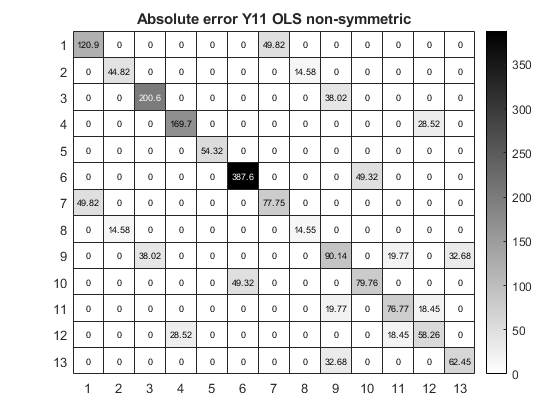

[ols_froeb_error, ols_max_error, chart] = error_metrics(Y11, Y11_hat, 'Y11 OLS non-symmetric');

Froebius norm for Y11 OLS symmetric is 539.6034
Max norm for Y11 OLS symmetric is 387.6481


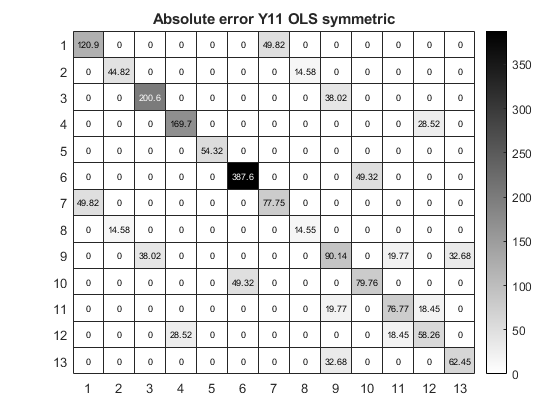

[ols_froeb_error, ols_max_error, chart] = error_metrics(Y11, Y11_hat_sym, 'Y11 OLS symmetric');

Froebius norm for Y22 OLS non-symmetric is 224.5246
Max norm for Y22 OLS non-symmetric is 169.4936


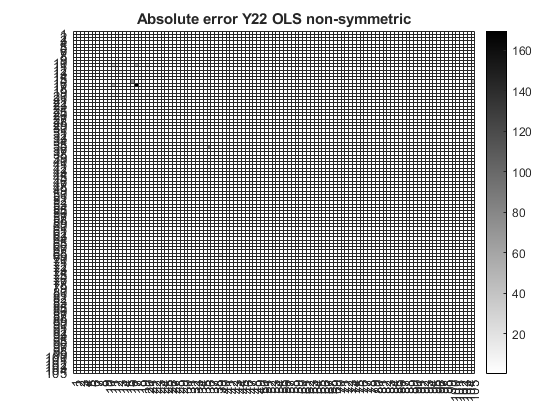

[ols_froeb_error, ols_max_error, chart] = error_metrics(Y22, Y22_hat, 'Y22 OLS non-symmetric');

Froebius norm for Y22 OLS symmetric is 221.1661
Max norm for Y22 OLS symmetric is 169.4936


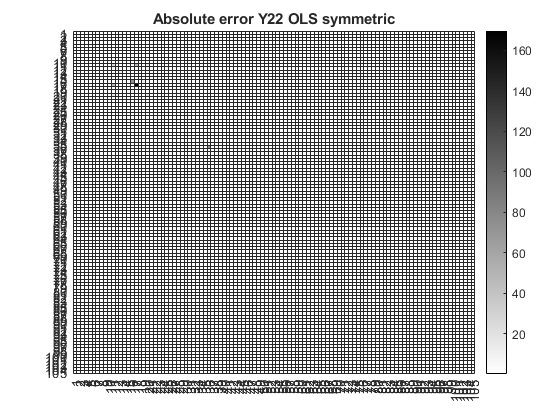

[ols_froeb_error, ols_max_error, chart] = error_metrics(Y22, Y22_hat_sym, 'Y22 OLS symmetric');

Froebius norm for Y OLS non-symmetric is 481175.0012
Max norm for Y OLS non-symmetric is 213239.1184


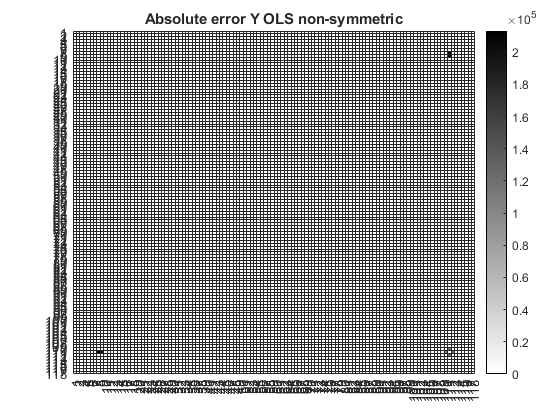

[ols_froeb_error, ols_max_error, chart] = error_metrics(Y, Y_hat, 'Y OLS non-symmetric');

[ols_froeb_error, ols_max_error, chart] = error_metrics(Y, Y_hat_sym, 'Y OLS symmetric');

Froebius norm for Y OLS symmetric is 101108.9969
Max norm for Y OLS symmetric is 44803.0323


Since the rank is hard to define, here is an analysis of the performances depending of the value of the rank.

progressive_partitioning(Y, bus_voltage, bus_current, T, 25)


$$\begin{array}{l}
\left(V^T \otimes 1_N \right)*\textrm{vec}\left(Y\right)=\textrm{vec}\left(I\right)\\
\textrm{Considering}\;\textrm{symmetry}\\
\left(V^T \otimes 1_N \right)*Q_y *x=\textrm{vec}\left(I\right)\\
\textrm{Can}\;\textrm{be}\;\textrm{generalized}\;\textrm{by}:\\
A*x=b
\end{array}$$



$$\begin{array}{l}
{\hat{Y} } ={\textrm{argmin}}_y \left\|A*x-b{\left\|\right.}_2 \right.\\
\textrm{Lasso}:{\hat{Y} } ={\textrm{argmin}}_y \left\|A*x-b{\left\|\right.}_2 +\lambda \right\|x{\left\|\right.}_1 \\
\textrm{Adaptative}\;\textrm{Lasso}:{\hat{Y} } ={\textrm{argmin}}_y \left\|A*x-b{\left\|\right.}_2 +\lambda \Sigma \frac{x_i }{{\hat{x} }_i }\right.
\end{array}$$


$T*V=\left\lbrack \begin{array}{c}
\textrm{v1}\\
\textrm{v2}
\end{array}\right\rbrack$, $\;T*I=\left\lbrack \begin{array}{c}
\textrm{i1}\\
\textrm{i2}
\end{array}\right\rbrack$, $\;T^{\;} *Y*T^{-1\;\;} =\left\lbrack \begin{array}{cc}
Y_{1,1}  & Y_{1,2} \\
Y_{1,2}^T  & Y_{2,2} 
\end{array}\right\rbrack$


$$\left\lbrack \begin{array}{cc}
Y_{1,1}  & Y_{1,2} \\
Y_{1,2}^T  & Y_{2,2} 
\end{array}\right\rbrack *\left\lbrack \begin{array}{c}
X*v_2 \\
v_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
i_1 \\
i_2 
\end{array}\right\rbrack$$



$$\begin{array}{l}
-{\mathit{\mathbf{X}}}^{\mathit{\mathbf{T}}} *{\mathit{\mathbf{Y}}}_{1,1} *\mathit{\mathbf{X}}+{\mathit{\mathbf{Y}}}_{2,2} =\mathit{\mathbf{C}},\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;C=I_2 *V_2^{\dagger } -{\left(V_2^{\dagger } \right)}^T *I_1^T *X\\

\end{array}$$



$$\begin{array}{l}
-\left(X^T \bigotimes X^T \right)*\textrm{vec}\left(Y_{1,1} \right)+\textrm{vec}\left(Y_{2,2} \right)=\textrm{vec}\left(C\right)\\

\end{array}$$



$$\left\lbrack \begin{array}{cc}
-\left(X^T \bigotimes X^T \right) & I
\end{array}\right\rbrack *\left\lbrack \begin{array}{c}
\textrm{vec}\left(Y_{1,1} \right)\\
\textrm{vec}\left(Y_{2,2} \right)
\end{array}\right\rbrack =\textrm{vec}\left(C\right)\;\Leftrightarrow A*x=b\;$$



$$\begin{array}{l}
I_2 =\left(Y_{1,2}^T *X+Y_{2,2} \right)*V_2 \\
X^T *Y_{1,2} =I_2 *V_2^{\dagger } -Y_{2,2} \iff A*x=b
\end{array}$$



$$\hat{Y} =T^{-1} *\left\lbrack \begin{array}{cc}
Y_{1,1}  & Y_{1,2} \\
Y_{1,2}^T  & Y_{2,2} 
\end{array}\right\rbrack *T$$
